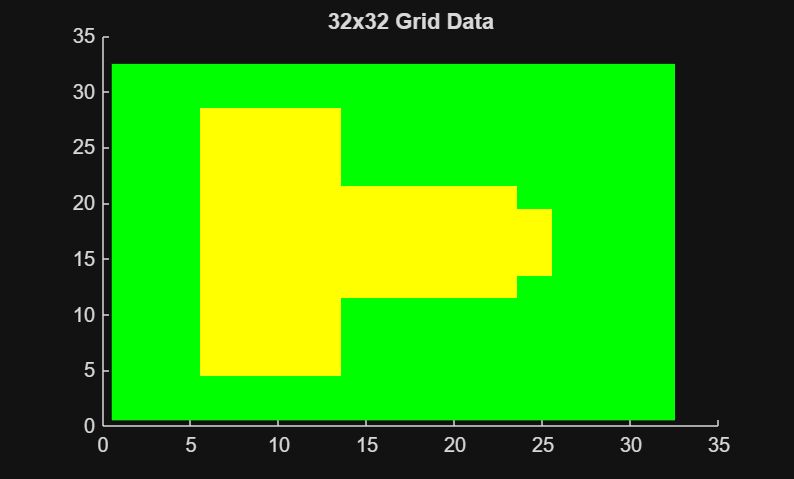

clear
% Update file path
load('C:\Users\<...>\github\Microwave-Filter-Dataset\Testing Data\H-100.mat')


topologies = cat(3,dataset.topology);
solutions = [dataset.solution];

selectionIdx = 1;

grid = squeeze(grids(:,:,1));
solution = solutions(selectionIdx);
S = solution.S;
Z = solution.Zref;
F = solution.Freq;

figure
hold on 
imagesc(grid)
colormap([1 1 0; 0 1 0])
title('32x32 Grid Data')

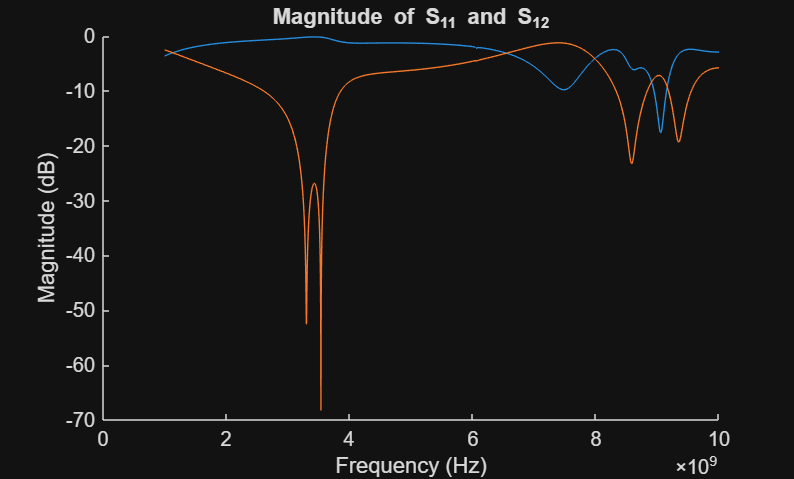


S11 = squeeze(S(1,1,:));
S12 = squeeze(S(1,2,:));

figure
hold on 
plot(F,20*log10(abs(S11)),DisplayName='S_{11}')
plot(F,20*log10(abs(S12)),DisplayName='S_{12}')
colormap([1 1 0; 0 1 0])

xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Magnitude of S_{11} and S_{12}')